# TPA 1 Grupo 10

A continuación se resuelve el trabajo de aplicación 1.

## Inciso 1

El rango admisible de la entrada/salida es de 5V.

## Inciso 2

Se hizo un código en c que permite generar una señal de PWM con ciclo de trabajo variable.

Con esta señal de entrada, se ingresó primero al 20% durante

clear;
close all;
s = tf('s');

TIME_DIFF = 1e-3;


## Se cargan los datos

% addpath('c:\Users\tomi\Github\facu3\Control 3\TPA\1');
% savepath;
data = open('prot_sim_data.dat');

## Se grafican los datos de la simulacion

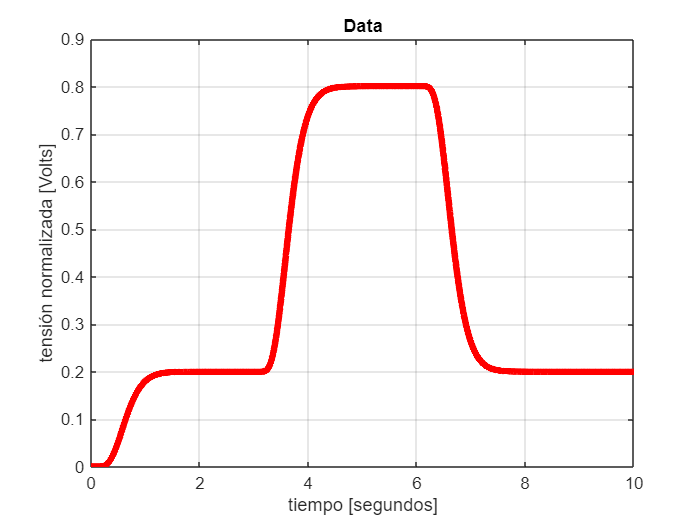

time = data.data(:,1);
y6 = data.data(:,7)/5; % se normaliza con respecto a 5V

h=figure();
plot(time, y6, 'r', 'linewidth', 4);
hold on;
grid on;
xlabel('tiempo [segundos]');
ylabel('tensión normalizada [Volts]');
title('Data');
saveas(h, 'Datos', 'png');

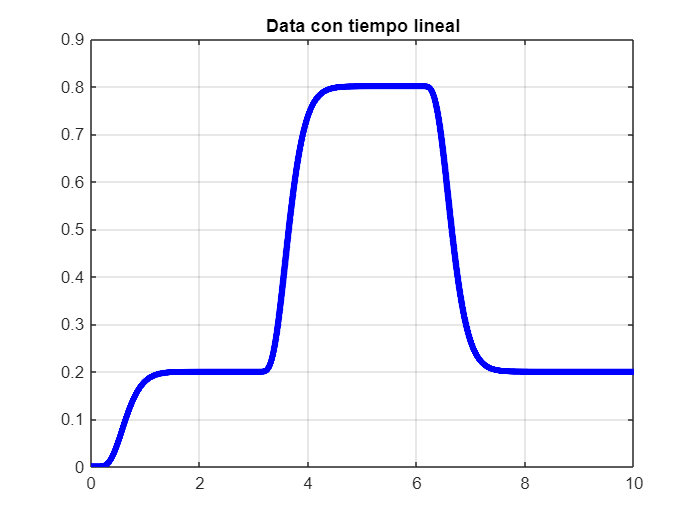


lineal_time = 0:TIME_DIFF:10;
lineal_y6 = interp1(time, y6, lineal_time);

figure;
plot(lineal_time, lineal_y6, 'b', 'linewidth', 4);
hold on;
grid on;
title('Data con tiempo lineal');

## Modelo FOPDT

MEAS_DELAY = 0.0753;

step_resp = lineal_y6((3/TIME_DIFF):(5/TIME_DIFF));
step_resp=step_resp-0.2; % muevo los datos 0.2 porque se comenzó con 20% de duty cycle
step_resp=step_resp/0.6; % escalo a que la referencia sea 1, porque se puso 80% de duty cycle como step
step_time = lineal_time(1:length(step_resp));
step_input = ones(1, length(step_resp));
for i=1:length(step_resp)
    step_input(i) = step_time(i) > MEAS_DELAY;
end

close all;
fig = figure;
set(fig,'Position',[0 0 800 600]);
plot(step_time, step_resp, 'b', 'linewidth', 6);
hold on;
grid on;
title('Respuesta al escalón (de 20% a 80% ciclo de trabajo)');
xlabel('Tiempo [Segundos]');
ylabel('Tensión normalizada (a 5V) [Volts]');
plot(step_time, step_input, '--r', 'linewidth', 2);

% De los graficos generados se estima el delay
fopdt_delay = 0.33791+MEAS_DELAY;
% De System Identification se obtuvieron los siguientes parámetros
fopdt_time_constant = 0.28802;
fopdt_gain = 1;

% Modelo FOPDT resultante
fopdt_estimated = fopdt_gain/(s*fopdt_time_constant+1);
fopdt_estimated.inputDelay = fopdt_delay;

[fopdt_est_y, fopdt_est_t] = step(fopdt_estimated, step_time); fopdt_est_y=reshape(fopdt_est_y, size(step_resp));
plot(fopdt_est_t, fopdt_est_y, 'k', 'linewidth', 2);
error_fopdt = immse(step_resp, fopdt_est_y);
fprintf('El error cuadrático medio entre la estimada y los datos es: %f\n', error_fopdt);

El error cuadrático medio entre la estimada y los datos es: 0.001007


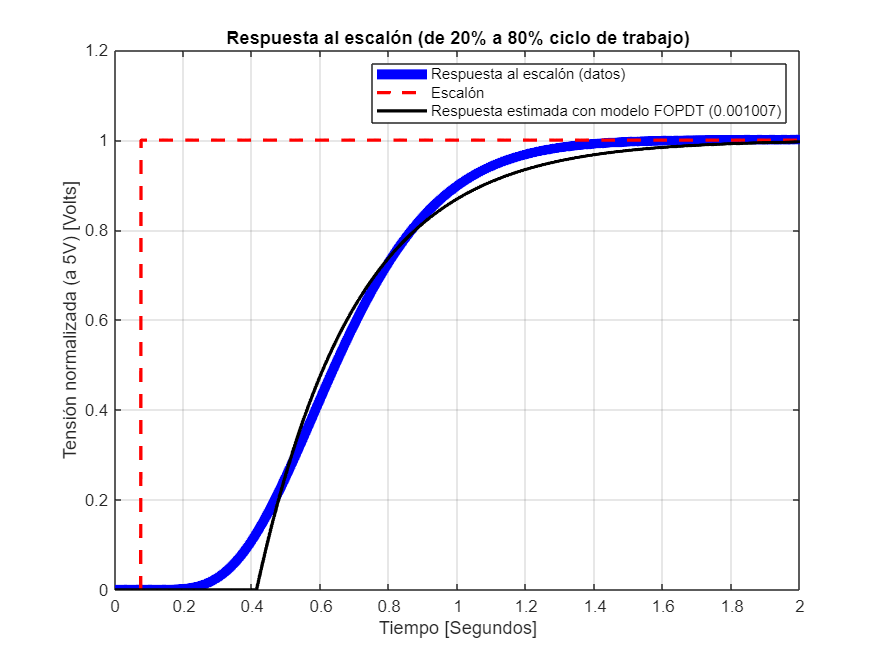

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt));

## Modelo SOPDT

% Parámetros obtenidos de System Identification
sopdt_delay = 0.24087;
sopdt_time_constant_1 = 0.18561;
sopdt_time_constant_2 = 0.18561;
sopdt_gain = 1;

% Modelo SOPDT resultante
sopdt_estimated = sopdt_gain/((s*sopdt_time_constant_1+1)*(s*sopdt_time_constant_1+1));
sopdt_estimated.inputDelay = sopdt_delay+MEAS_DELAY;

[sopdt_est_y, sopdt_est_t] = step(sopdt_estimated, step_time); sopdt_est_y=reshape(sopdt_est_y, size(step_resp));
plot(sopdt_est_t, sopdt_est_y, 'm', 'linewidth', 2);

error_sopdt = immse(step_resp, sopdt_est_y);
fprintf('El error cuadrático medio (SOPDT) entre la estimada y los datos es: %f\n', error_sopdt);

El error cuadrático medio (SOPDT) entre la estimada y los datos es: 0.000242



fprintf('La mejora del modelo SOPDT contra FOPDT es de "%f%%"\n', (error_fopdt-error_sopdt)/error_fopdt);

La mejora del modelo SOPDT contra FOPDT es de "0.759223%"


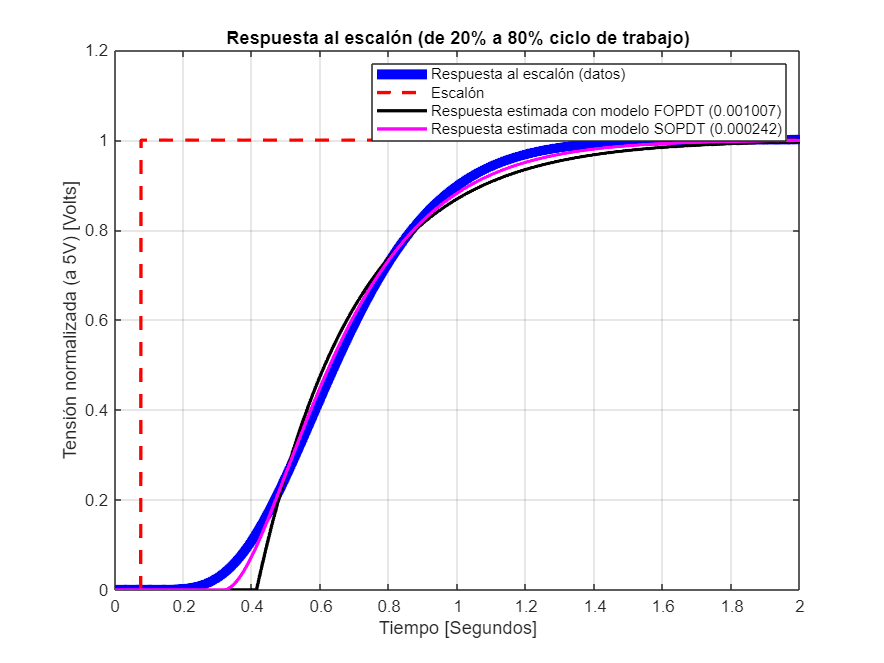

legend('Respuesta al escalón (datos)', 'Escalón', sprintf('Respuesta estimada con modelo FOPDT (%f)', error_fopdt), sprintf('Respuesta estimada con modelo SOPDT (%f)', error_sopdt));

saveas(fig, 'resp_escalon_fopdt_sopdt', 'png');

## Modelo de las ecuaciones en diferencias

Modelo completo a partir de las ecuaciones en diferencias

Tiene un retardo porque el micro tiene un retardo cuando actúa

R1=10e3;
C1=10e-6;
complete_model = 1/((R1*C1*s+1)^6);
complete_model.InputDelay = 0.0753;

[ec_diff_y, ec_diff_t] = step(complete_model, step_time); ec_diff_y=reshape(ec_diff_y, size(step_resp));
figure; hold on; grid on;
plot(step_time, step_resp, 'b', 'linewidth', 4);
title('Respuesta al escalón (de 20% a 80% ciclo de trabajo)');
xlabel('Tiempo [Segundos]');
ylabel('Tensión normalizada (a 5V) [Volts]');
plot(step_time, step_input, '--r', 'linewidth', 2);

plot(ec_diff_t, ec_diff_y, 'g', 'linewidth', 2);

error_ec_diff = immse(step_resp, ec_diff_y);
fprintf('El error cuadrático medio (SOPDT) entre la estimada y los datos es: %f\n', error_ec_diff);

El error cuadrático medio (SOPDT) entre la estimada y los datos es: 0.000001


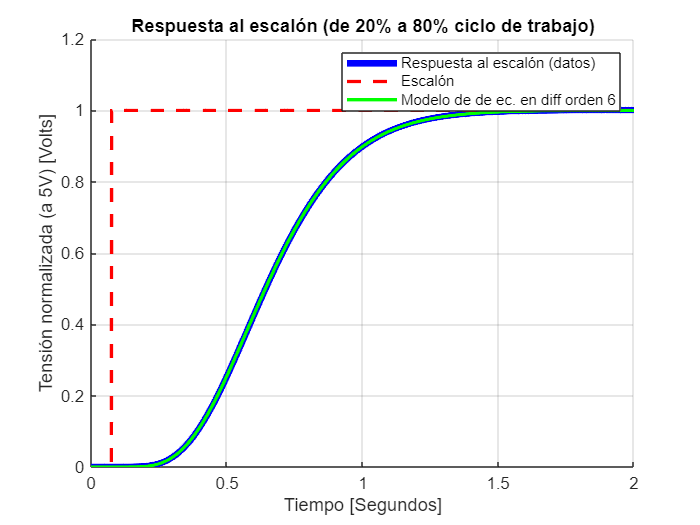

legend('Respuesta al escalón (datos)', 'Escalón', 'Modelo de de ec. en diff orden 6');

## Modelo de alto orden con System Identification

high_order_model = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06);
high_order_model.InputDelay = MEAS_DELAY;

[high_y, high_t] = step(high_order_model, step_time); high_y=reshape(high_y, size(step_resp));
% close all;
% plot(step_time, step_resp, 'b', 'linewidth', 4);
% hold on;
% grid on;
% plot(step_time, step_input, '--r', 'linewidth', 2);
plot(high_t, high_y, 'g', 'linewidth', 2);

error_high = immse(step_resp, high_y);
fprintf('El error cuadrático medio (alto orden) entre lo estimado y los datos es: %f\n', error_high);

El error cuadrático medio (alto orden) entre lo estimado y los datos es: 0.000000


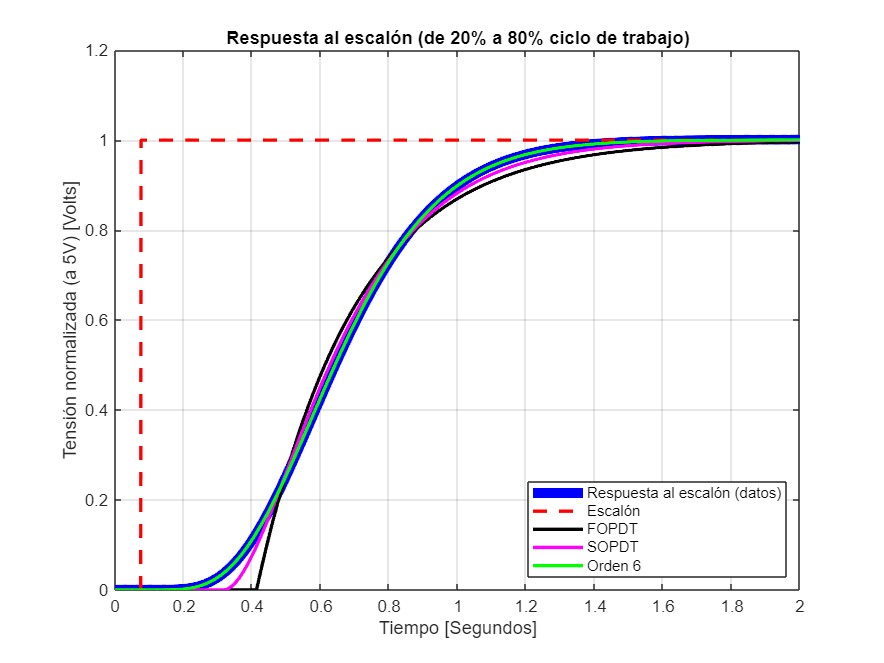

legend('Respuesta al escalón (datos)', 'Escalón', 'FOPDT', 'SOPDT', 'Orden 6', 'Location', 'southeast');

saveas(fig, 'resp_esc', 'png');

## Señal PRBS

data_prbs = open('prot_sim_data_prbs.dat');

## Extraigo los datos de la simulación

El ensaño se hace un 7 bits y considerando un tiempo de rising de 2 segundos. Por lo que el ensayo debería durar TEST_DURATION segundos

IMPORTANTE ARREGLAR LA FRECUENCIA DE MUESTREO, tiene que se como 10 veces más grande

BITS=7;
SAMPLING_TIME=1.4/BITS

SAMPLING_TIME = 0.2000

TEST_DURATION=(2^BITS-1)*SAMPLING_TIME

TEST_DURATION = 25.4000

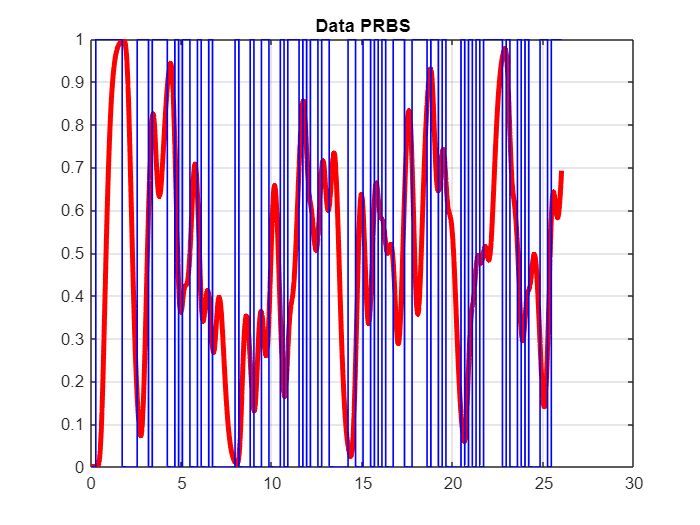

MAX_TIME=26;

DIEZMADO_POR = 2;

time_prbs = data_prbs.data(:,1);
pwm_prbs = data_prbs.data(:,2)/5;  % divido por 5 para normalizar los datos con respecto al pico de 5v
y6_prbs = data_prbs.data(:,3)/5; % divido por 5 para normalizar los datos con respecto al pico de 5v

% pwm_prbs = pwm_prbs - mean(pwm_prbs);
% y6_prbs = y6_prbs - mean(y6_prbs);

figure();
plot(time_prbs, y6_prbs, 'r', 'linewidth', 3);
hold on;
grid on;
title('Data PRBS');
plot(time_prbs, pwm_prbs, 'b', 'linewidth', 1);

lineal_time_prbs = 1:(1/50):(MAX_TIME-3/50);
lineal_pwm_prbs = interp1(time_prbs(1:DIEZMADO_POR:length(time_prbs)), pwm_prbs(1:DIEZMADO_POR:length(time_prbs)), lineal_time_prbs)

lineal_pwm_prbs =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0017    0.0014    0.0011    0.0009    0.0008    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002


lineal_y6_prbs = interp1(time_prbs(1:DIEZMADO_POR:length(time_prbs)), y6_prbs(1:DIEZMADO_POR:length(time_prbs)), lineal_time_prbs)

lineal_y6_prbs =     0.7382    0.7626    0.7816    0.7999    0.8182    0.8365    0.8537    0.8677    0.8803    0.8919    0.9035    0.9129    0.9216    0.9303    0.9381    0.9448    0.9505    0.9558    0.9612    0.9650    0.9689    0.9727    0.9757    0.9782    0.9807    0.9832    0.9851    0.9868    0.9884    0.9900    0.9910    0.9920    0.9930    0.9938    0.9945    0.9951    0.9957    0.9962    0.9965    0.9968    0.9970    0.9967    0.9961    0.9946    0.9919    0.9858    0.9792    0.9727    0.9630    0.9486



mean(lineal_pwm_prbs)

ans = 0.5037

mean(lineal_y6_prbs)

ans = 0.5016

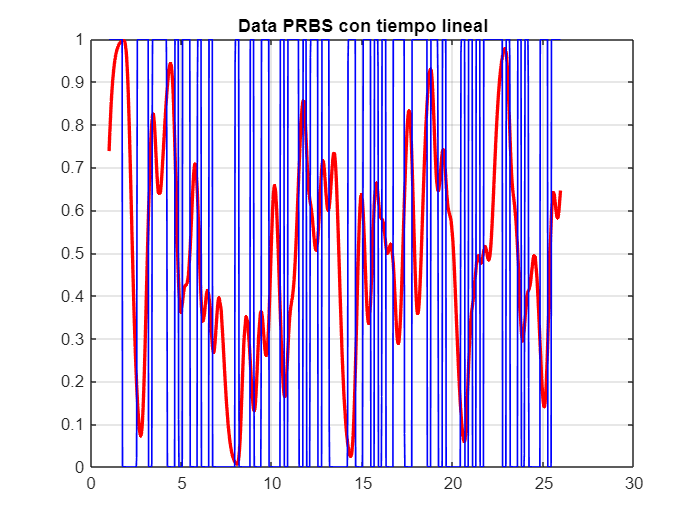


figure;
plot(lineal_time_prbs, lineal_y6_prbs, 'r', 'linewidth', 2);
hold on;
grid on;
title('Data PRBS con tiempo lineal');
plot(lineal_time_prbs, lineal_pwm_prbs, 'b', 'linewidth', 1);


% Datos de ajuste de los modelos con el System Identification
FOPDT_prbs = 1/(0.42546*s+1);
FOPDT_prbs.InputDelay = 0.30792;

SOPDT_prbs = 1/((0.2242*s+1)*(0.22423*s+1));
SOPDT_prbs.InputDelay = 0.21874;


## Familia de modelos (incertidumbre)

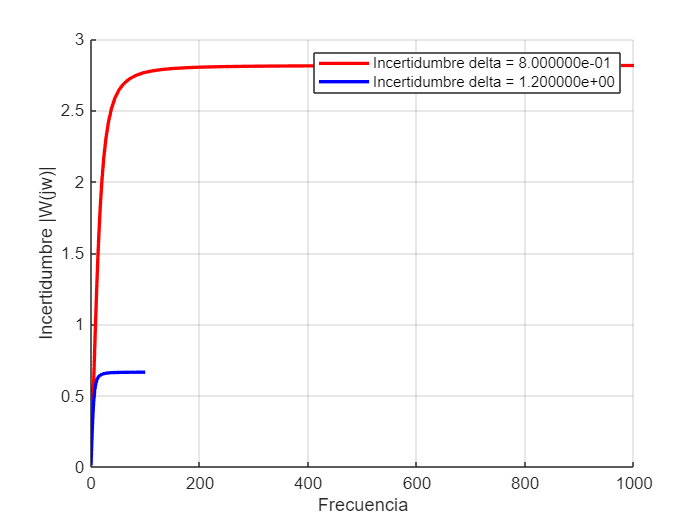

R=10e3;
C=10e-6;
Tp = R*C;


delta = [0.8, 1.2];

Ws1 = 1 - ((Tp*s+1)/(delta(1)*Tp*s+1))^6;
Ws2 = 1 - ((Tp*s+1)/(delta(2)*Tp*s+1))^6;

[w1y, w1x] = freqresp(Ws1); w1y = reshape(w1y, size(w1x));
[w2y, w2x] = freqresp(Ws2); w2y = reshape(w2y, size(w2x));

figure; hold on; grid on;
semilogx(w1x, abs(w1y), 'r', 'LineWidth', 2);
semilogx(w2x, abs(w2y), 'b', 'LineWidth', 2);

xlabel('Frecuencia');
ylabel('Incertidumbre |W(jw)|');
legend(sprintf('Incertidumbre delta = %d', delta(1)), sprintf('Incertidumbre delta = %d', delta(2)));


% modelo de incertidumbre que contiene a la nuestra
w_slope = (1.286-0.602)/(10.8252-4.95825)

w_slope = 0.1166

b = 0.601608-4.95825*w_slope

b = 0.0235


% plot(w1x, w1x*w_slope+b, 'k', 'LineWidth', 2);


## TPA 2

% K=0.5;
% a=0.28802;
% PI1 = K*(a*s+1)/s;
% 
% fopdt_estimated.InputDelay = 0;
% CL1 = fopdt_estimated/(1+fopdt_estimated*PI1);
% 
% [pid_y, pid_x] = step(CL1);
% 
% figure;
% plot(pid_x, pid_y, 'r', 'linewidth', 3);
% xlabel('Tiempo [segundos]');
% ylabel('Amplitud normalizada [Volts]');